# **2108332 Adjustment Computation**

## **LAB 1 Linearization**

**ชื่อ-นามสกุล: วสุพล คล้ายขำ**

**รหัสประจำตัวนิสิต: 6631137221**

#### $y_1 ,y_2$ เป็นฟังก์ชั่นของ $x_1 ,x_2 ,x_3$ดังนี้

#### 
$$y_1 =5x_1 x_2^2 +3x_1^2 +x_1 -x_2$$


#### 
$$y_2 =x_2^2 -2x_1 x_2 +3x_2 +7$$


### 1. ให้ทำข้อย่อยต่อไปนี้ด้วยมือ

#### 1.1 คำนวณหาเมทริกซ์จาโคเบียนของ $y_1 ,y_2$ เมื่อ $x_1$ = 2, $x_2$ = -3

คำตอบ:

 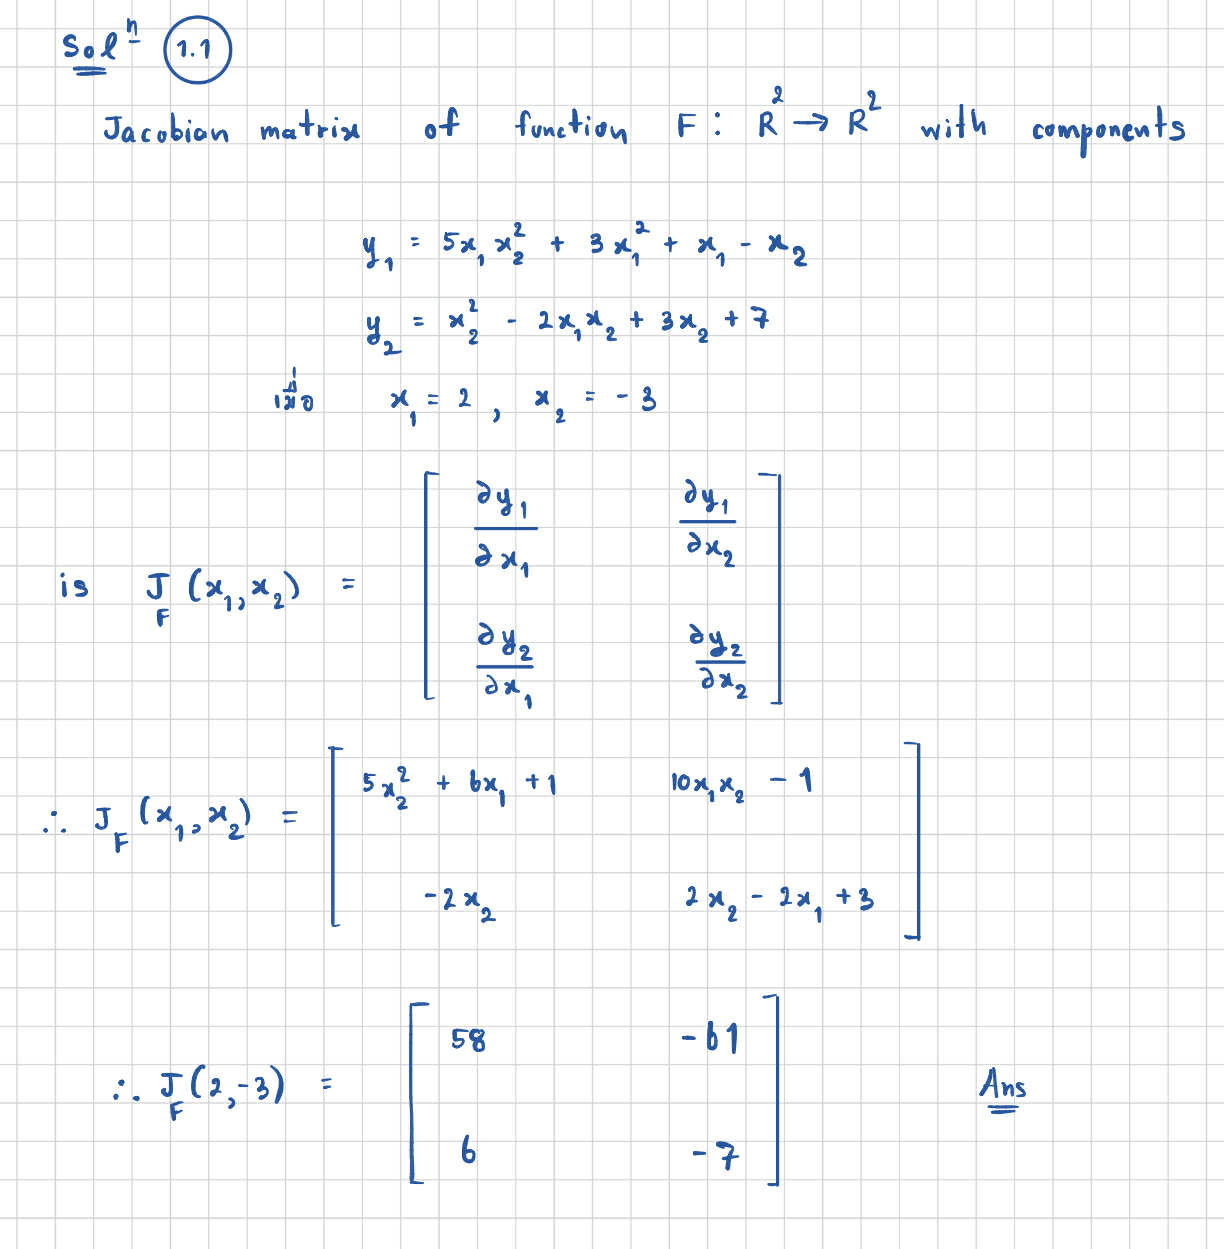

#### 1.2 แปลง $y_1 ,y_2$ ให้เป็นเชิงเส้นที่ $x_1$ = 1, $x_2$ = 3 แล้วคำนวณหาค่าฟังก์ชันที่แปลงเป็นเชิงเส้นแล้วเมื่อ $x_1$ = 1, $x_2$ = 4

คำตอบ:

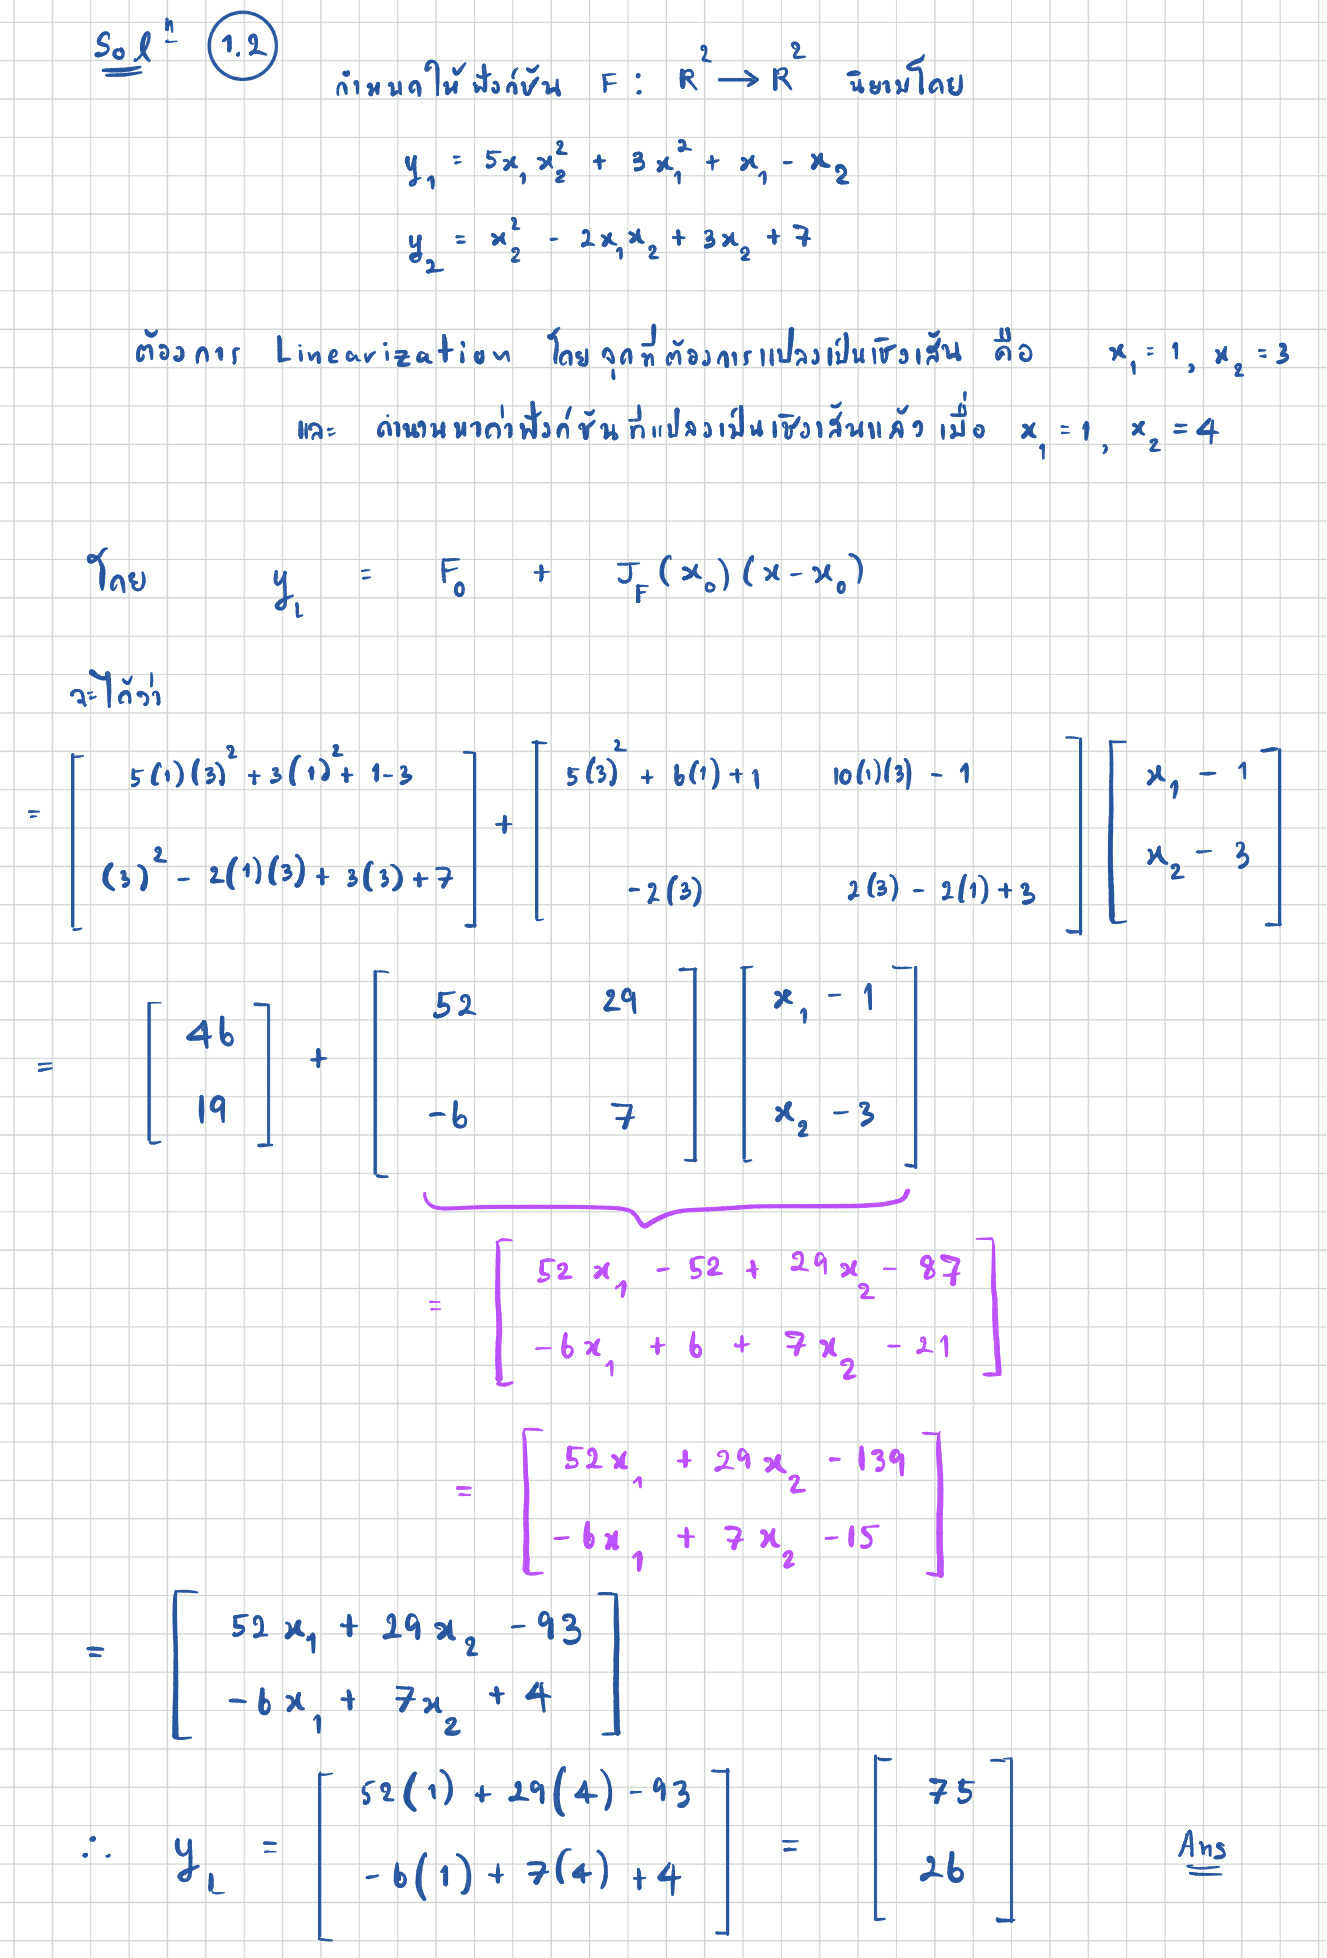

### 2. ให้เขียน MATLAB script สำหรับหาคำตอบข้อ 1.1 และ 1.2

- ขึ้นต้นด้วยคำสั่ง clear และ format long g

- แสดงผลเมทริกซ์จาโคเบียนที่คำนวณได้

- แสดงผลฟังก์ชันที่แปลงเป็นเชิงเส้นแล้ว

- แสดงผลค่าของฟังก์ชันที่แปลงเป็นเชิงเส้นแล้วเมื่อ $x_1 =1,x_2 =4$

clear
format long g
syms x1 x2
y1 = 5 * x1 * x2^2 + 3 * x1^2 + x1 - x2;
y2 = x2^2 - 2 * x1 * x2 + 3 * x2 + 7;
f = [y1;
    y2];
j = jacobian(f,[x1 x2]);
j_ans = subs(j,{x1 x2},{2 -3});
disp(j_ans)

$$\left(\begin{array}{cc} 58 & -61\\ 6 & -7 \end{array}\right)$$

x0 = [1;
    3];
x = [x1;
    x2];
f0 = subs(f,{x1 x2},{x0(1) x0(2)});
j0 = subs(j,{x1 x2},{x0(1) x0(2)});
y = f0 + j0 * (x - x0);
disp(y)

$$\left(\begin{array}{c} 52\,x_{1}+29\,x_{2}-93\\ 7\,x_{2}-6\,x_{1}+4 \end{array}\right)$$

y_ans = f0 + j0 * (subs(x,{x1 x2},{1,4}) - x0);
disp(y_ans)

$$\left(\begin{array}{c} 75\\ 26 \end{array}\right)$$